# Part 4: ばね質点モデルで見る電力系統

電力系統で何が起きているのかを頭の中で思い描くのは、簡単ではありません。交流で送るので式には三角関数が必ず現れ（非線形）、試験用の系統でも母線や発電機は数十あり（ノードが多い）、そもそも電圧も電流も目に見えません。そのため、「負荷が増えると周波数はなぜ下がるのか」「電力系統の慣性とは何か」「過渡安定性が崩れるとき何が起きているのか」といった問いに、直感で答えるのは難しくなります。

この Part では、電気の系統を、思い描ける機械の系に置き換えます。各母線の電圧を平面の上の点、送電線をその間のばねと見るのです。この見方は以前からあり、野田モデルは 2 ノードの系統を機械のモデルで説明し、Gronquist らは多数の発電機を含む系統を、フェーザの平面上の質点とばねのアニメーションとして見せました。このライブスクリプトでは、まずばねの式を潮流計算の結果で数値として確かめ、そのあと GUILDA の `plot_spring_model` で、潮流、周波数の低下、脱調、電圧崩壊を、ばねと質点の動きとして見ていきます。

**この Part で分かること**

- 電圧を平面上の点（フェーザ）、送電線をばねと見る考え方と、その式（ばねの力 $F_{ij} = B_{ij}(V_j - V_i)$ と、その接線・半径方向への分解）

- 潮流計算の解が、すべてのばねがつり合う位置になる理由と、負荷が増えたときのばねの伸び

- 負荷の増加で絵全体が回る（周波数が下がる）ことと、慣性・ガバナの働き

- 事故の除去が遅れると、ばねが伸び切って脱調すること

- 漏斗の形の曲面 $z = \log|V|$ の上で、電圧崩壊が質点の滑り落ちる動きとして見えること

知識ページ: [Part 4: 可視化機能：ばね質点モデル](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part4-spring-mass-model.html","-browser"))（ブラウザで開きます）。知識ページのグラフは、すべてこのライブスクリプトで描けます。

**注意**: GUILDA を起動してから（`>> GUILDA`）実行してください。上のリンクも、起動した GUILDA の場所からページを開きます。全体の実行には 1〜2 分かかります。

## 1. 電圧を平面上の点として置く

各母線の電圧は 50 Hz または 60 Hz の正弦波です。平常の運転では、すべての母線が同じ周波数で振動していて、違うのは振幅と波のずれ（位相）だけです。そこで、定格の周波数で回る座標から波を見ると、振動は消え、各母線の電圧は止まった矢印になります。これが**フェーザ**です。


$$v_i(t) = \sqrt{2}\,|V_i|\cos\bigl(2\pi f_0 t + \theta_i\bigr) \quad\longleftrightarrow\quad V_i = |V_i|\,e^{j\theta_i}$$


$v_i(t)$ は母線 $i$ の電圧の瞬時値、$|V_i|$ はその実効値、$\theta_i$ は位相、$f_0$ は定格の周波数です。矢印の長さが電圧の大きさ、角度が位相です。

同梱の IEEE 9 母線系統（発電機 3 台、負荷 3 つ）の潮流計算を解き、9 つの母線の電圧を平面に置いてみます。

net = network.IEEE9bus(LocalController=true);
[pf, flag] = net.calculate_powerflow();
flag

flag = 1

cv_V = pf.tab_bus.Vphasor;                             % 電圧フェーザ [pu]
sv_bus = string(pf.tab_bus.Properties.RowNames);
pf.tab_bus(:, ["V", "Varg", "Vphasor"])

ans = 9×3 table
               V         Varg            Vphasor     
            _______    _________    _________________

    B001       1.04            0       1.04+0i       
    B002      1.025      0.16197     1.0116+0.16529i 
    B003      1.025     0.081415     1.0216+0.083358i
    B004     1.0258     -0.03869      1.025-0.039678i
    B005    0.99563    -0.069618    0.99322-0.069258i
    B006     1.0127    -0.064357     1.0106-0.065127i
    B007     1.0258     0.064921     1.0236+0.066547i
    B008     1.0159     0.012698     1.0158+0.012899i
    B009     1.0324     0.034326     1.0317+0.035429i


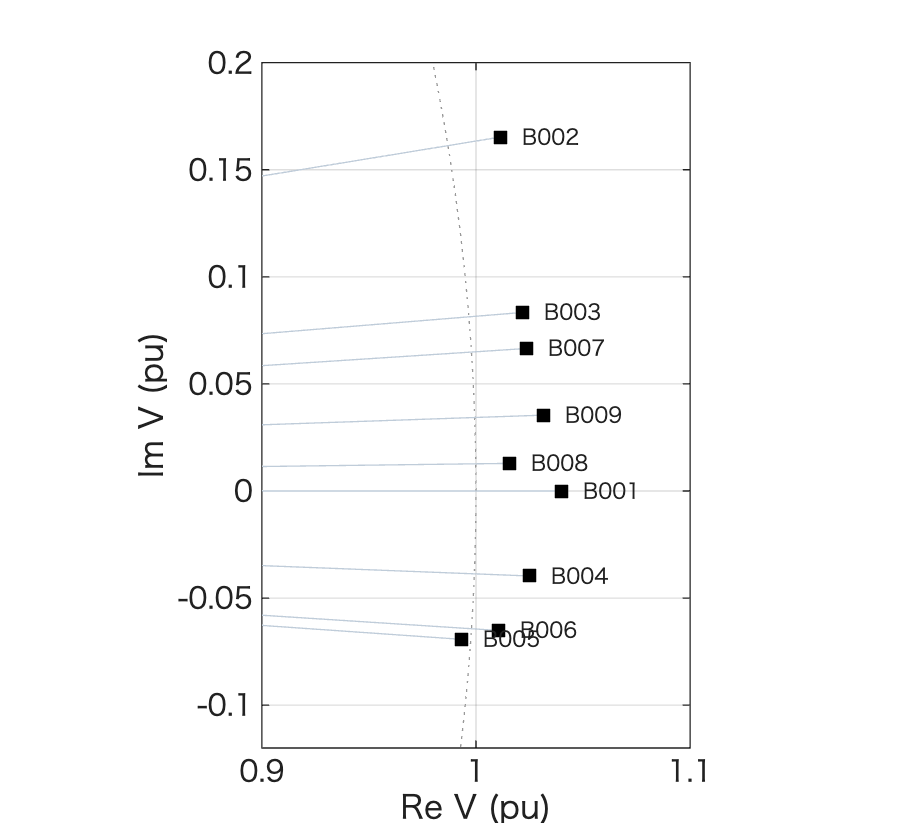


figure(Position=[100 100 460 420]);
ax = axes; hold(ax, "on");
rv_th = linspace(0, 2 * pi, 361);
plot(ax, cos(rv_th), sin(rv_th), ":", Color=[0.6 0.6 0.6]);    % |V| = 1 の円
plot(ax, [zeros(9, 1), real(cv_V)]', [zeros(9, 1), imag(cv_V)]', Color=[0.75 0.8 0.85]);
plot(ax, real(cv_V), imag(cv_V), "s", MarkerSize=6, MarkerFaceColor="k", Color="k");
text(ax, real(cv_V) + 0.01, imag(cv_V), sv_bus, FontSize=8);
axis(ax, "equal"); xlim(ax, [0.9, 1.1]); ylim(ax, [-0.12, 0.2]); grid(ax, "on"); box(ax, "on");
xlabel(ax, "Re V (pu)"); ylabel(ax, "Im V (pu)");

原点から見ると、9 つの点はすべて半径 1 前後の円の近くに、少しずつ違う角度で並んでいます（図は点のまわりを拡大しています）。発電機の母線（`B001`〜`B003`）は角度が進み、負荷の母線（`B005`、`B006`、`B008`）は遅れています。すべての母線の点を同じ平面に置くと、系統全体の状態が点の並びとして 1 枚の絵になります。

平常の運転では、点は止まっています。系統の周波数が定格より低くなると、どの波も回る座標より遅れていくので、すべての点がそろって時計回りに回り始めます。高くなると反時計回りです。周波数の変化は、絵全体の回転として見えます（4 節）。

## 2. 送電線をばねに見立てる

次に、点どうしをつなぎます。母線 $i$ から母線 $j$ への送電線に流れ込む電流は、2 つの電圧の差に比例します。送電線の抵抗と対地静電容量を無視して、リアクタンス $X_{ij}$ だけでできているとすると、アドミタンスは $y_{ij} = 1/(jX_{ij}) = -jB_{ij}$（$B_{ij} = 1/X_{ij}$）で、次の式になります。


$$I_{ij} = y_{ij}\,(V_i - V_j)$$



$$F_{ij} := -j\,I_{ij} = B_{ij}\,(V_j - V_i)$$


2 つ目の式はフックの法則（ばねの力 ＝ ばね係数 × 伸び、向きは相手の端へ）と同じ形です。「伸び」は 2 つの点の差 $V_j - V_i$、「ばね係数」は送電線のサセプタンス $B_{ij} = 1/X_{ij}$、「力」$F_{ij}$ は電流を −90° 回したもの（$-j$ を掛けたもの）です。短くて太い送電線（$X$ が小さい）ほど、硬いばねになります。

この力を、$V_i$ を通る円に沿う成分（接線方向）と、半径に沿う成分（半径方向）に分けます。母線 $i$ から送電線へ送り出す複素電力を $S_{ij} = V_i\,\overline{I_{ij}} = P_{ij} + jQ_{ij}$ とすると、$V_i$ の向きから見た力は次のようになります。


$$e^{-j\theta_i}\,F_{ij} = -\,\frac{Q_{ij} + j\,P_{ij}}{|V_i|}$$


実部が半径方向、虚部が接線方向の成分です。ばねは母線 $i$ を、円に沿って後ろへ $P_{ij}/|V_i|$ の力（中心のまわりのトルクはちょうど $P_{ij}$）で、中心へ向かって $Q_{ij}/|V_i|$（無効電流）の力で引きます。つまり、**有効電力は円に沿う向きのトルク、無効電流は中心に向かう向きの力**です。

### 潮流計算の結果で確かめる

この分解は $S_{ij} = V_i\overline{I_{ij}}$ の書き換えなので、抵抗や対地静電容量があっても成り立ちます。潮流計算の結果のブランチの表（`tab_branch`）には、両端の母線 `From`・`To`、送り端の電力 `Pfrom`、`Qfrom` と電流 `Ifrom` が入っています。母線の表（`tab_bus`）の電圧フェーザ `Vphasor` と合わせて、左辺（`Fcurrent`、電流から）と右辺（`Fpower`、電力から）を計算し、ブランチの表に列として足して比べます。

tab_br = pf.tab_branch(:, ["From", "To", "Pfrom", "Qfrom", "Ifrom"]);
cv_Vfrom = pf.tab_bus{tab_br.From, "Vphasor"};                                   % 送り端の電圧
cv_Vto = pf.tab_bus{tab_br.To, "Vphasor"};                                       % 受け端の電圧
tab_br.Fcurrent = exp(-1j * angle(cv_Vfrom)) .* (-1j * tab_br.Ifrom);           % e^{-jθi} F_ij
tab_br.Fpower = -(tab_br.Qfrom + 1j * tab_br.Pfrom) ./ abs(cv_Vfrom);           % -(Q + jP)/|Vi|
tab_br(:, ["From", "To", "Fcurrent", "Fpower"])

ans = 9×4 table
              From       To           Fcurrent               Fpower      
             ______    ______    __________________    __________________

    ET001    "B001"    "B004"     -0.26006-0.68886i     -0.26006-0.68886i
    ET002    "B002"    "B007"    -0.064914-1.5902i     -0.064914-1.5902i 
    ET003    "B003"    "B009"      0.10595-0.82927i      0.10595-0.82927i
    EL004    "B004"    "B005"     -0.22318-0.39908i     -0.22318-0.39908i
    EL005    "B004"    "B006"    -0.010041-0.29932i    -0.010041-0.29932i
    EL006    "B005"    "B007"      0.11362+0.8469i       0.11362+0.8469i 
    EL007    "B006"    "B009"      0.13288+0.5872i       0.13288+0.5872i 
    EL008    "B007"    "B008"     0.007773-0.74461i     0.007773-0.74461i
    EL009    "B008"    "B009"      0.23916+0.23719i      0.23916+0.23719i


2 つの列は一致します。たとえば `EL008`（母線 7 → 8）は虚部（接線方向）が約 −0.74 です。母線 7 から 8 へ 0.76 pu の有効電力を送っていることが、母線 7 を後ろへ引く力 $P/|V| = 0.764/1.026$ として現れています。

### 有効電力は角度の差で決まる

半径 $|V_i|$ と $|V_j|$ の円の上にあり、角度の差が $\delta = \theta_i - \theta_j$ の 2 つの点では、上の式の虚部から、ばねのトルクは次のようになります。


$$P_{ij} = B_{ij}\,|V_i|\,|V_j|\,\sin\delta$$


損失のない送電線で送る有効電力の、おなじみの式です。アドミタンス行列の非対角要素 $Y_{ij} = -y_{ij}$ からばね係数 $B_{ij} = \mathrm{Im}\,Y_{ij}$ を取り出し、この式の値を潮流計算の `Pfrom` と比べます。

[~, iv_from] = ismember(tab_br.From, sv_bus);      % Y の行と列の番号（tab_bus の順）
[~, iv_to] = ismember(tab_br.To, sv_bus);
tab_br.B = imag(pf.cm_Y(sub2ind(size(pf.cm_Y), iv_from, iv_to)));               % ばね係数 B_ij [pu]
tab_br.delta = angle(cv_Vfrom) - angle(cv_Vto);                                  % 角度の差 [rad]
tab_br.Pspring = tab_br.B .* abs(cv_Vfrom) .* abs(cv_Vto) .* sin(tab_br.delta);  % B|Vi||Vj|sinδ
tab_br(:, ["From", "To", "B", "delta", "Pspring", "Pfrom"])

ans = 9×6 table
              From       To        B         delta      Pspring      Pfrom  
             ______    ______    ______    _________    ________    ________

    ET001    "B001"    "B004"    17.361      0.03869     0.71641     0.71641
    ET002    "B002"    "B007"        16     0.097046        1.63        1.63
    ET003    "B003"    "B009"    17.065      0.04709        0.85        0.85
    EL004    "B004"    "B005"    11.604     0.030928     0.36647     0.40937
    EL005    "B004"    "B006"    10.511     0.025667     0.28021     0.30704
    EL006    "B005"    "B007"    5.9751     -0.13454    -0.81853     -0.8432
    EL007    "B006"    "B009"    5.5882    -0.098683    -0.57557    -0.59463
    EL008    "B007"    "B008"    13.698     0.052223      0.7451      0.7638
    EL009    "B008"    "B009"    9.7843    -0.021628    -0.22191    -0.24095


変圧器（`ET001`〜`ET003`、抵抗なし）では 2 つの値は一致し、送電線（`EL004`〜`EL009`）でも 1 割ほどの差に収まります。差は送電線の抵抗によるものです（$\sin\delta$ の式は抵抗を無視しています）。どのブランチでも、電力は角度が進んだ点から遅れた点へ流れ、角度の差が大きいほど、ばねが伝える電力は大きくなります。ただし 5 節で見るように、それには限界があります。

## 3. 潮流計算はばねのつり合い

母線につながる機器は、その点を押したり引いたりします。発電機は系統へ電力を送り出すので、点を円に沿って前（反時計回り）へトルク $P$ で押します。負荷は電力を取り出すので、点を後ろへ引きます。ばねは、どの点でも、その押す力・引く力を打ち消すところまで伸びます。母線 $i$ の機器が注入する電力を $S_i = P_i + jQ_i$ とすると、母線での力のつり合いは次の式です。


$$f_i + \sum_{j} F_{ij} = 0, \qquad f_i = e^{j\theta_i}\,\frac{Q_i + j\,P_i}{|V_i|}$$


2 節の分解から、これは母線の電力方程式 $S_i = \sum_j S_{ij}$ と同じです。つまり、**潮流計算は、すべてのばねがつり合う位置を求める計算**で、そのときの点の角度と半径が、潮流計算の解の電圧フェーザです。

ばねだけでは決まらないことが 1 つあります。絵全体を同じ角度だけ回しても、どのばねの長さも変わらず、力のつり合いもそのままです。この回転対称性があるので、潮流計算では角度を固定する（ふつうは 0 にする）slack 母線が必要になります。slack 母線は絵の基準の向きを決めるだけで、物理的には何も変えません。

GUILDA は、系統全体についてこの絵を `plot_spring_model` で描きます。`initialize` で平衡点を求めてから、`net.plot_spring_model` で描きます（知識ページの図。点の付近を拡大し、母線の名前を省いています）。

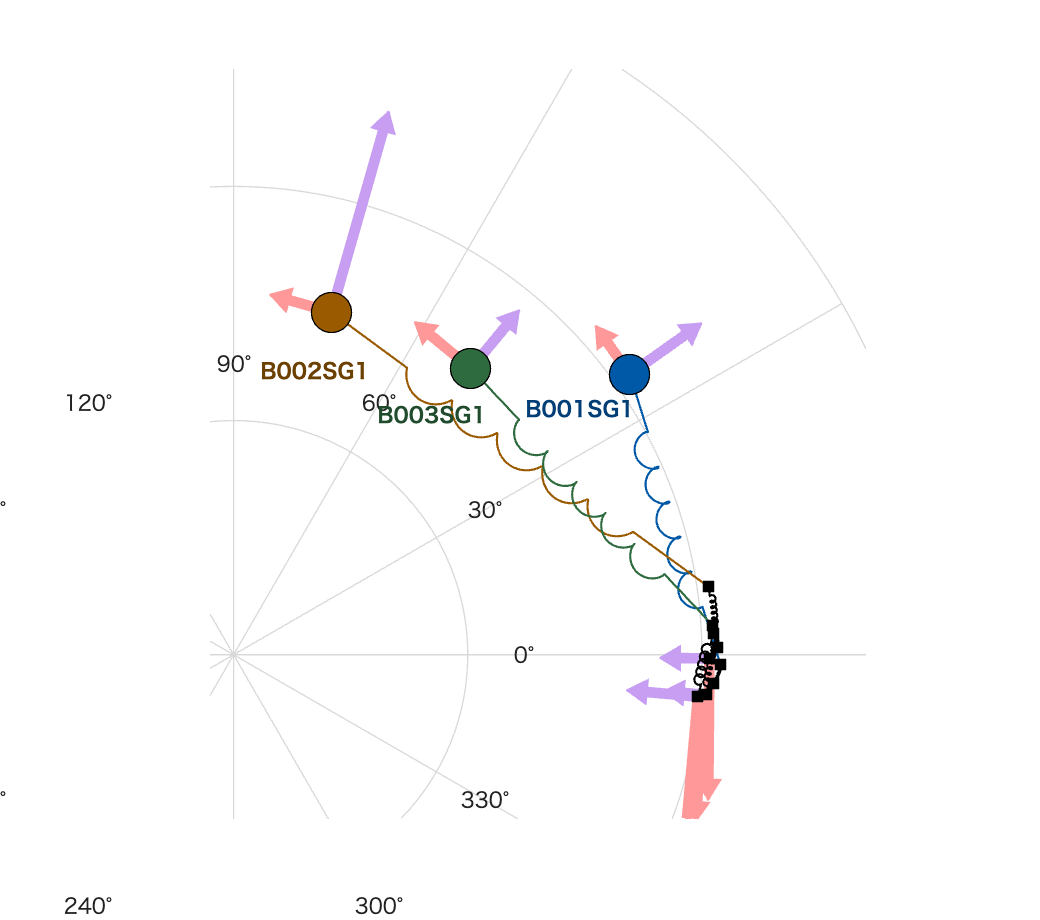

[~, flag] = net.initialize();
c_blue = [0 89 167] / 255;      % 図の色（知識ページの図と同じ）
c_orange = [154 91 0] / 255;
c_green = [46 107 63] / 255;
figure(Position=[100 100 520 460]);
ax = axes;
G = net.plot_spring_model(Parent=ax);
G.ShowValue = false;
G.ShowLegend = false;
G.NodeLabel(G.sct_data.sv_kind == "bus") = "";
G.set_style("B001SG1", Color=c_blue);
G.set_style("B002SG1", Color=c_orange);
G.set_style("B003SG1", Color=c_green);
set(ax, XLim=[-0.05, 1.35], YLim=[-0.35, 1.25]);
set(findall(ax, "Type", "text"), FontSize=8);

黒い四角が 9 つの母線、大きな丸が 3 台の発電機（`B001SG1` が青、`B002SG1` が橙、`B003SG1` が緑）の内部電圧で、発電機のリアクタンスのばねで母線とつながっています。桃色の矢印が有効電力 $P$、紫の矢印が無効電流 $I_q$ です。発電機の点は母線より前（反時計回りの向き）にあり、母線を前へ押しています。

**注意**: 図は母線の位相角の平均が 0 になる向きで描くので、全体の向きは 1 節の図（`B001` が 0）と少しずれます。比べるのは点どうしの位置の差です。

### 負荷を増やすと、ばねが伸びる

3 つの負荷を 1.5 倍にして潮流計算を解き、もとの負荷の場合と並べて描きます。負荷の引く力が強くなると、ばねはどれだけ伸びるでしょうか。もとの `net` は後の節で使うので、負荷を増やす系統は別に読み込みます。

netHeavy = network.IEEE9bus(LocalController=true);
tab_load = netHeavy.get_parameter("powerflow", Key="load-impedance")   % 3 つの負荷の P、Q

tab_load = 3×2 table
                  P        Q  
                _____    _____

    B005LRX1    -1.25     -0.5
    B006LRX1     -0.9     -0.3
    B008LRX1       -1    -0.35


tab_load.P = 1.5 * tab_load.P;
tab_load.Q = 1.5 * tab_load.Q;
netHeavy.set_parameter("powerflow", tab_load);
[pfHeavy, flag] = netHeavy.calculate_powerflow();
flag

flag = 1

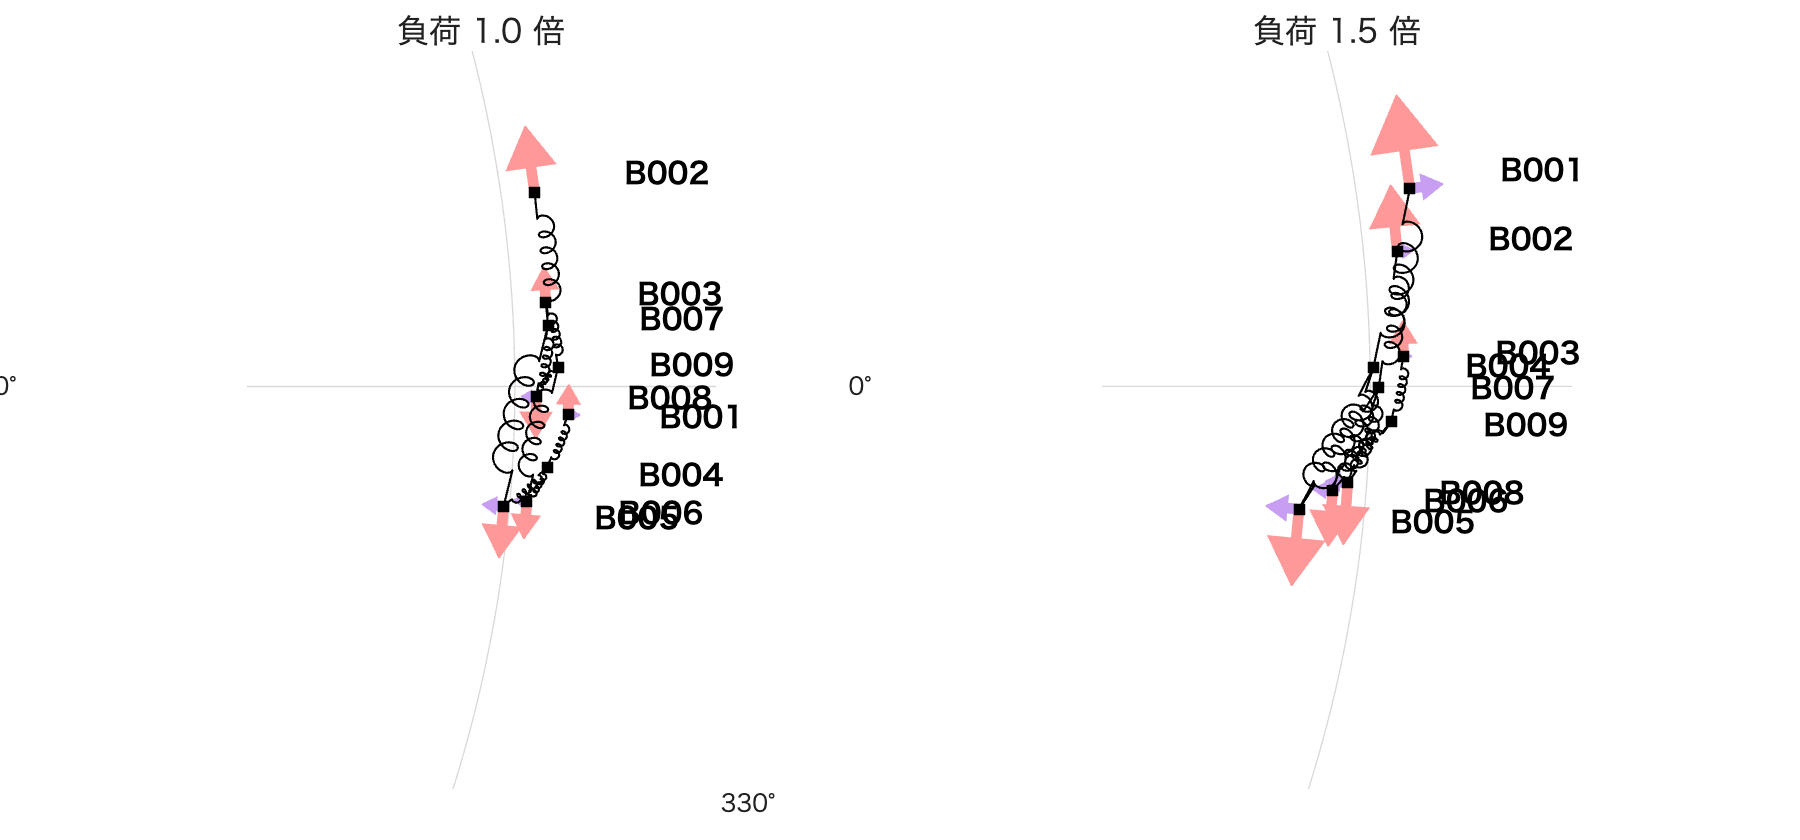

figure(Position=[100 100 900 420]);
layout = tiledlayout(1, 2, TileSpacing="compact", Padding="compact");
c_pf = {pf, pfHeavy};
sv_title = ["負荷 1.0 倍", "負荷 1.5 倍"];
for i = 1:2
    G = c_pf{i}.plot_spring_model(Parent=nexttile(layout));
    G.ShowValue = false;
    G.ShowLegend = false;
    G.ArrowScaleP = 0.03;
    G.ArrowScaleQ = 0.03;
    axis(G.ax, [0.8 1.15 -0.3 0.25])
    title(G.ax, sv_title(i))
end

tab_angle = pf.tab_bus(:, ["Varg", "V"]);              % 1.0 倍の位相 [rad] と大きさ [pu]
tab_angle.VargHeavy = pfHeavy.tab_bus.Varg;             % 1.5 倍
tab_angle.VHeavy = pfHeavy.tab_bus.V;
tab_angle

tab_angle = 9×4 table
              Varg          V       VargHeavy    VHeavy 
            _________    _______    _________    _______

    B001            0       1.04            0       1.04
    B002      0.16197      1.025    -0.044152      1.025
    B003     0.081415      1.025      -0.1202      1.025
    B004     -0.03869     1.0258     -0.12824     1.0024
    B005    -0.069618    0.99563     -0.23831    0.95138
    B006    -0.064357     1.0127      -0.2218    0.97508
    B007     0.064921     1.0258     -0.14308     1.0063
    B008     0.012698     1.0159     -0.21508    0.98589
    B009     0.034326     1.0324     -0.16805      1.016


1.5 倍では、slack 母線（`B001`）と負荷の母線（`B005`、`B006`、`B008`）の間が大きく開き、点の並びが長くなっています。増えた負荷は slack 母線の発電機が引き受けるので、`B001` から負荷の母線へ向かうばねが伸び、角度の差が開きます。表では、`B005` の位相が −0.070 rad（−4.0°）から −0.238 rad（−13.7°）へ遅れ、`B001` との角度の差が 3 倍以上に開いています。$P = B|V_i||V_j|\sin\delta$ から、同じばねでより多くの電力を送るには角度の差を広げるしかない、ということが絵に表れています。負荷の母線の点は円の内側へも少し下がり（電圧の低下）、これは負荷の無効電力が点を中心へ引く力が強まったためです。

**注意**: 潮流計算の結果は発電機の状態を持たないので、`ResultPF` の `plot_spring_model` は母線だけを描きます。発電機の点まで描くには、`net.plot_spring_model` を使います。

## 4. 周波数が下がる理由と慣性

ここまでは、発電機を単に押す力として扱ってきました。動きを見るために、発電機にも自分の点を持たせます。リアクタンスの奥にある内部電圧の点です。この点は発電機の回転子に当たるので、質量（慣性 $M$）を持ちます。タービンが機械入力でこの点を前へ押し、母線へのばねが送り出す電気出力の分だけ後ろへ引きます。母線の点には質量がなく、いつでもすぐにつり合いの位置へ移ります。点の運動は、まさに動揺方程式 $M\dot{\omega} = P_\mathrm{m} - P_\mathrm{e} - D\omega$ です。

この絵にそのまま合うように、同梱の IEEE 9 母線系統を変えます。3 台の発電機を古典モデル（`gen-classical`。過渡リアクタンス $X_d'$ の奥の内部電圧の大きさ $|E|$ が一定）に、3 つの負荷を定電力負荷（`load-power`）に置き換えます。$M$ と $D$ は同梱のデータのまま、$X_d = X_q = X_d'$ とします。この置き換えは 4〜6 節で何度か使うので、ライブスクリプトの最後にある関数 `build_classical_ieee9` にまとめています。古典モデルは AVR・PSS を持たないので、置き換えのときに外れます（その警告は関数の中で止めています）。

netCl = build_classical_ieee9();
[~, flag] = netCl.initialize()

flag = 1

t = 1 s に母線 5 の負荷の有効電力を 0.1 pu 増やし、8 秒まで計算します。ガバナはありません。`add_input` の値は平衡点の入力に足されます。`Pload` は母線へ注入する電力なので、負荷を増やすときは負の値にします。

scStep = netCl.add_scenario("step", Time=[0, 8]);
scStep.add_input("B005LPQ1", "Pload", -0.1, [1, 8]);
resStep = netCl.simulate("step", Progress="none");

結果を `plot_spring_model` で描き、`set_time` で時刻を選んで、t = 1、3、5、7 s の絵を並べます（知識ページの図）。

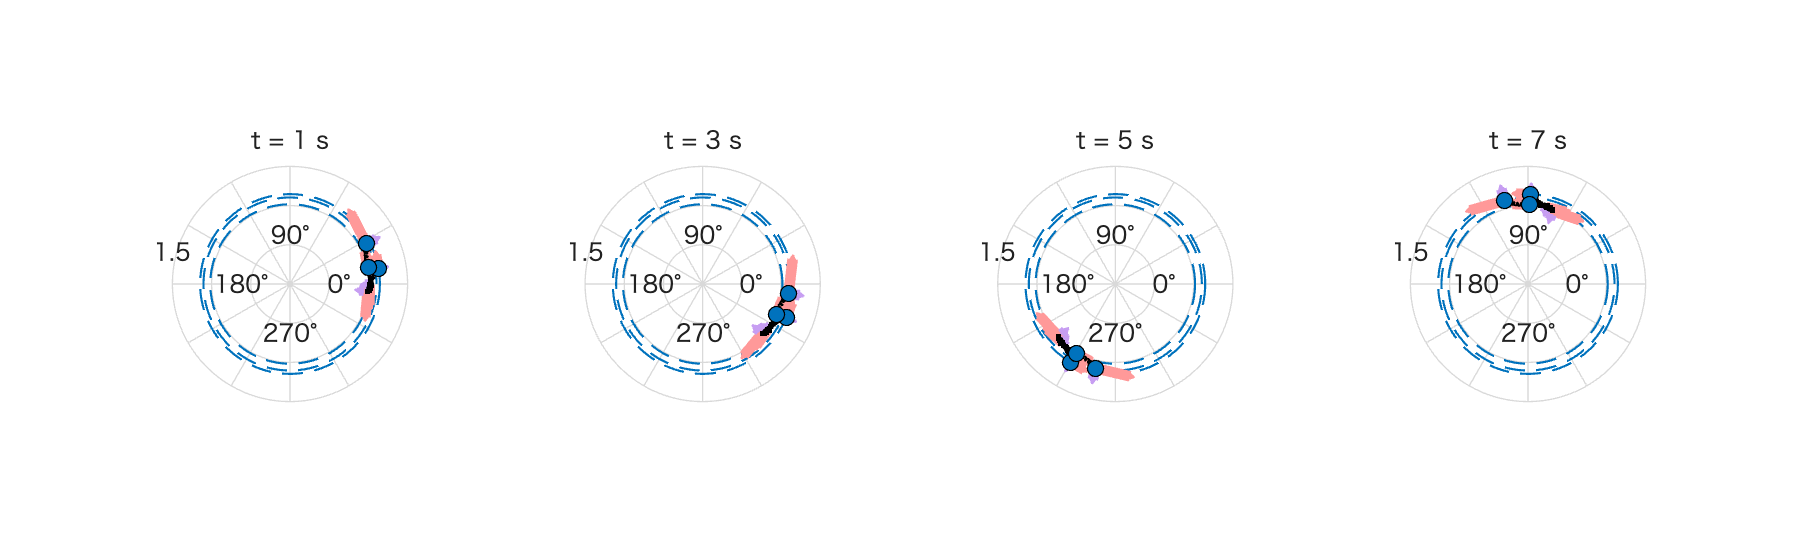

rr_t = [1, 3, 5, 7];
figure(Position=[100 100 900 280]);
layout = tiledlayout(1, numel(rr_t), TileSpacing="compact", Padding="compact");
for i = 1:numel(rr_t)
    ax = nexttile(layout);
    G = resStep.plot_spring_model(Parent=ax);
    G.ShowLabel = false;
    G.ShowValue = false;
    G.ShowLegend = false;
    G.NodeSize = G.NodeSize * 0.4;
    G.set_time(rr_t(i));
    title(ax, sprintf("t = %.0f s", rr_t(i)), FontWeight="normal", FontSize=9);
end

点の集まり全体が形を保ったまま時計回りに回り、そのまま回り続けます。破線の円は、一定に保たれる内部電圧の大きさです。回る座標の中で後ろへ回ることは、周波数が定格より低いということです。発電機の回転の速さでも確かめます。

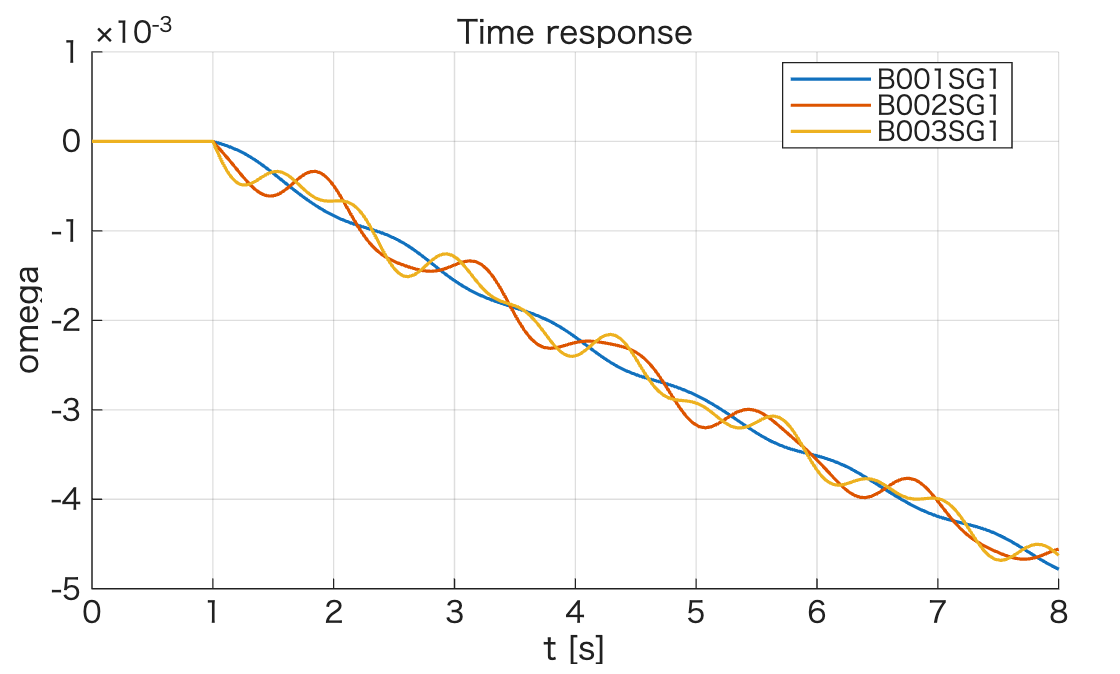

resStep.plot_trajectory(Quantity="omega");

回転の速さのずれ $\omega$ は、負荷を増やした直後から負になり、3 台がそろって下がります。ガバナがないので、8 秒でも定格より低いままで、絵は回り続けます。これで、最初の問いのうち 2 つに機械の言葉で答えられます。

- **周波数はなぜ下がる？** 負荷が増えると、その引く力がタービンの押す力より強くなります。余った引く力はばねを通してすべての点に伝わり、絵全体がそろって後ろへ回り始めます。

- **慣性とは？** 発電機の点が持つ質量のことです。重い点は急には動き出せないので、回転は滑らかに始まり、周波数は最初ゆっくり下がります。

### 慣性とガバナを変えて比べる

同じ負荷の増加を、(a) 上と同じ場合、(b) 3 台の発電機の慣性 $M$ を半分にした場合、(c) 3 台にガバナのモデル `gov-LPT1` を付けた場合の 3 つで、20 秒まで計算します（知識ページの図）。`Prate`（定格出力）は、平衡点の出力を負荷率 0.8 で割った値にします。

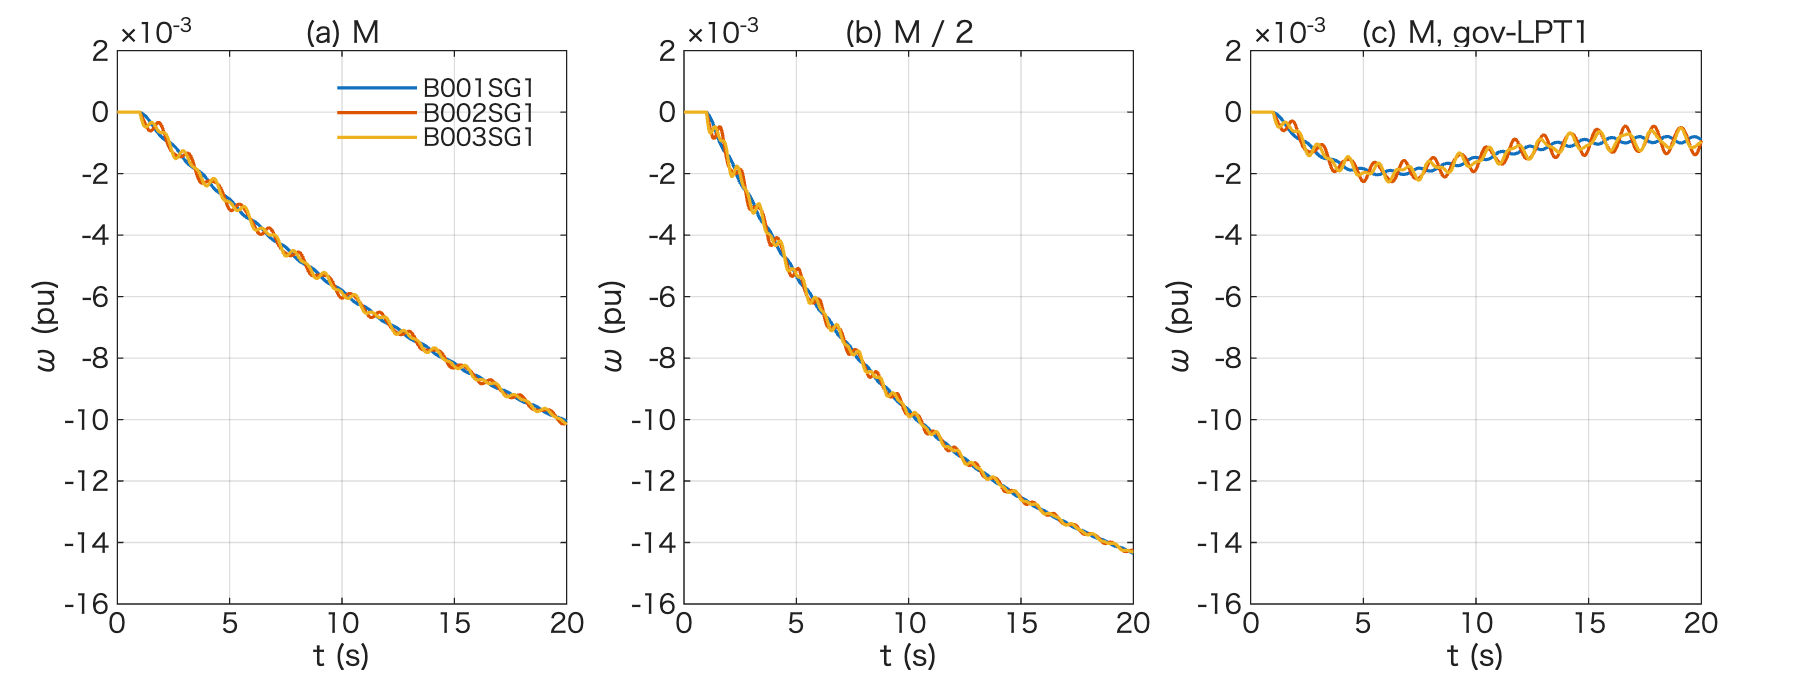

sr_title = ["(a) M", "(b) M / 2", "(c) M, gov-LPT1"];
c_resM = cell(1, 3);
rv_Mtotal = zeros(1, 3);        % 各場合の全体の慣性 [s]
for i_case = 1:3
    netCase = build_classical_ieee9();
    tab_dyn = netCase.get_parameter("dynamics", Key="gen-classical");
    if i_case == 2
        tab_dyn.M = tab_dyn.M / 2;
        netCase.set_parameter("dynamics", tab_dyn);
    elseif i_case == 3
        for s_gen = string(tab_dyn.Properties.RowNames)'
            gen = netCase.get_element(s_gen);
            gen.add_local_controller("gov-LPT1", parameter=struct(Prate=gen.rv_Uequilibrium(1) / 0.8));
        end
    end
    rv_Mtotal(i_case) = sum(tab_dyn.M);
    netCase.initialize();
    sc = netCase.add_scenario("step", Time=[0, 20]);
    sc.add_input("B005LPQ1", "Pload", -0.1, [1, 20]);
    c_resM{i_case} = netCase.simulate("step", Progress="none", SampleTime=0.01);
end
figure(Position=[100 100 900 340]);
layout = tiledlayout(1, 3, TileSpacing="compact", Padding="compact");
a_ax = gobjects(1, 3);
for i_case = 1:3
    a_ax(i_case) = nexttile(layout);
    c_resM{i_case}.plot_trajectory(Quantity="omega", Bus=["B001", "B002", "B003"], Parent=a_ax(i_case));
    title(a_ax(i_case), sr_title(i_case), FontWeight="normal");
    xlabel(a_ax(i_case), "t (s)"); ylabel(a_ax(i_case), "ω (pu)");
end
linkaxes(a_ax, "xy");
set(a_ax, XLim=[0, 20], XGrid="on", YGrid="on", Box="on");
legend(a_ax(2), "off"); legend(a_ax(3), "off");
set(a_ax(1).Legend, Location="northeast", Box="off");

慣性が小さいと（b）低下が早く始まり、ガバナがあると（c）ずれは小さく保たれます。初めの下がる速さは、系統全体を 1 台とみなすと $\mathrm{d}\omega/\mathrm{d}t = -\Delta P_\mathrm{L}/M$ です（$M$ は全体の慣性、$\Delta P_\mathrm{L} = 0.1$ pu）。慣性中心の速さ $\omega_\mathrm{COI} = \sum M_k\omega_k/\sum M_k$（`get_trajectory` の `Reference="COI"` で最後の列 `COI` に入ります）の、負荷を増やした直後 0.05 秒の傾きと比べます。

for i_case = 1:3
    tab_coi = c_resM{i_case}.get_trajectory("omega", Reference="COI");
    i_0 = find(tab_coi.t <= 1, 1, "last");      % 負荷を増やした時刻
    i_1 = find(tab_coi.t >= 1.05, 1);           % その 0.05 秒後
    r_slope = (tab_coi.COI(i_1) - tab_coi.COI(i_0)) / (tab_coi.t(i_1) - tab_coi.t(i_0));
    fprintf("%-16s M = %3.0f s: 式 -ΔP/M = %.6f pu/s、シミュレーション %.6f pu/s\n", ...
        sr_title(i_case), rv_Mtotal(i_case), -0.1 / rv_Mtotal(i_case), r_slope);
end

(a) M            M = 130 s: 式 -ΔP/M = -0.000769 pu/s、シミュレーション -0.000802 pu/s
(b) M / 2        M =  65 s: 式 -ΔP/M = -0.001538 pu/s、シミュレーション -0.001600 pu/s
(c) M, gov-LPT1  M = 130 s: 式 -ΔP/M = -0.000769 pu/s、シミュレーション -0.000802 pu/s


慣性を半分にすると、初めの下がる速さはほぼ 2 倍になります。ガバナは最初の瞬間にはまだ働かないので、(c) の初めの速さは (a) と同じです。ガバナは周波数のずれを検出して機械入力を増やし、押す力を強めて回転を遅くします。少しのずれは残り、それは AGC が数分かけて取り除きます（Part 8）。

## 5. 脱調：ばねが伸び切る

このモデルのばねには特徴があります。ばねの端が円の上を動くことです。角度 $\delta$ だけ前へずれた点に、ばねが与えるトルクを考えます。はじめは、点が離れるほどトルクは大きくなります。ところが 90° を超えると、ばねは円に沿う向きより中心の向きを向くようになり、ばねは長くなっているのに、点を引き戻すトルクは小さくなっていきます。これが 2 節の式 $P_{ij} = B_{ij}|V_i||V_j|\sin\delta$ の $\sin\delta$ です。ばねの長さ $|V_i - V_j|$ とトルクを、$\delta$ に対して描いて比べます（$|V_i| = |V_j| = 1$、$B_{ij} = 1$）。

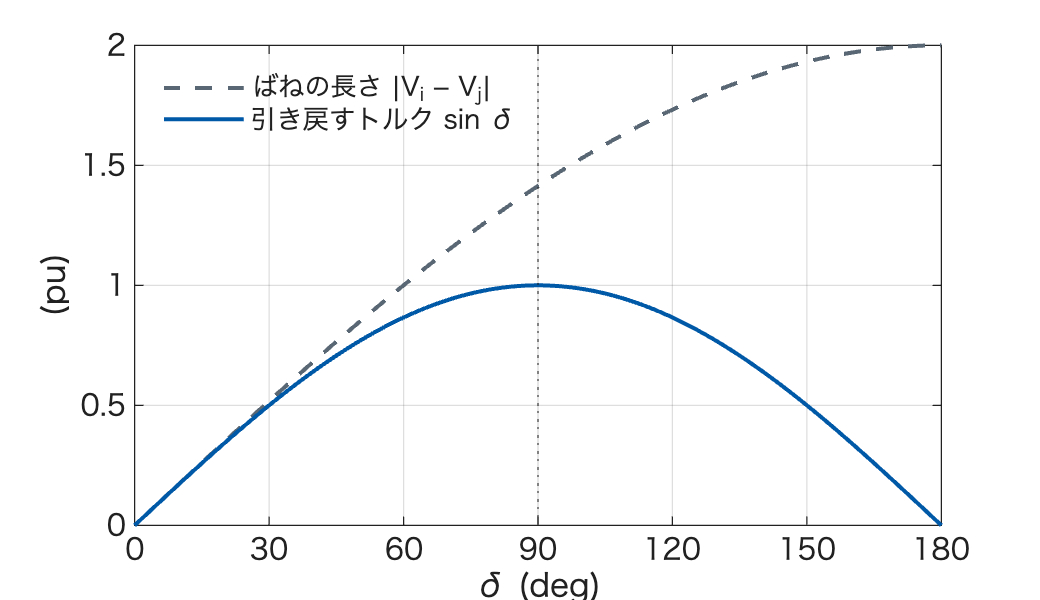

rv_d = linspace(0, 180, 181);
figure(Position=[100 100 520 300]);
ax = axes; hold(ax, "on");
plot(ax, rv_d, abs(1 - exp(1j * deg2rad(rv_d))), "--", Color=[0.35 0.4 0.45], LineWidth=1.5, DisplayName="ばねの長さ |V_i − V_j|");
plot(ax, rv_d, sind(rv_d), Color=c_blue, LineWidth=1.5, DisplayName="引き戻すトルク sin δ");
xline(ax, 90, ":", HandleVisibility="off");
set(ax, XLim=[0, 180], XTick=0:30:180, XGrid="on", YGrid="on", Box="on");
xlabel(ax, "δ (deg)"); ylabel(ax, "(pu)"); legend(ax, Location="northwest", Box="off");

ばねの長さは 180° まで増え続けますが、引き戻すトルクは 90° で最大になり、そのあとは減っていきます。これで 3 つ目の問いに答えられます。事故の間は、いくつかの発電機の電気出力が減る一方でタービンは押し続けるので、その点が前へ走り出します。事故を早く取り除けば、ばねが十分に引き戻せるうちに点をつかまえ、点は揺れながら戻ります。除去が遅れると、点が離れすぎて、ばねはもう引き戻せません。点は円を回って滑り、ほかの点と歩調をそろえられなくなります。**脱調とは、ばねが支えきれないところまで伸び切ること**です。

同梱の IEEE 9 母線系統（1 軸モデル、AVR・PSS 付き。1 節の `net`）で、t = 1 s から母線 7 を地絡させ、0.15 秒で除去する場合と 0.20 秒で除去する場合を比べます（Part 3 の回転子の角度のグラフと同じ条件）。それぞれを t = 1.1、1.5、1.9、2.4 s で描きます。母線に共通の回転は除きます（`RotationScale = 0`）。

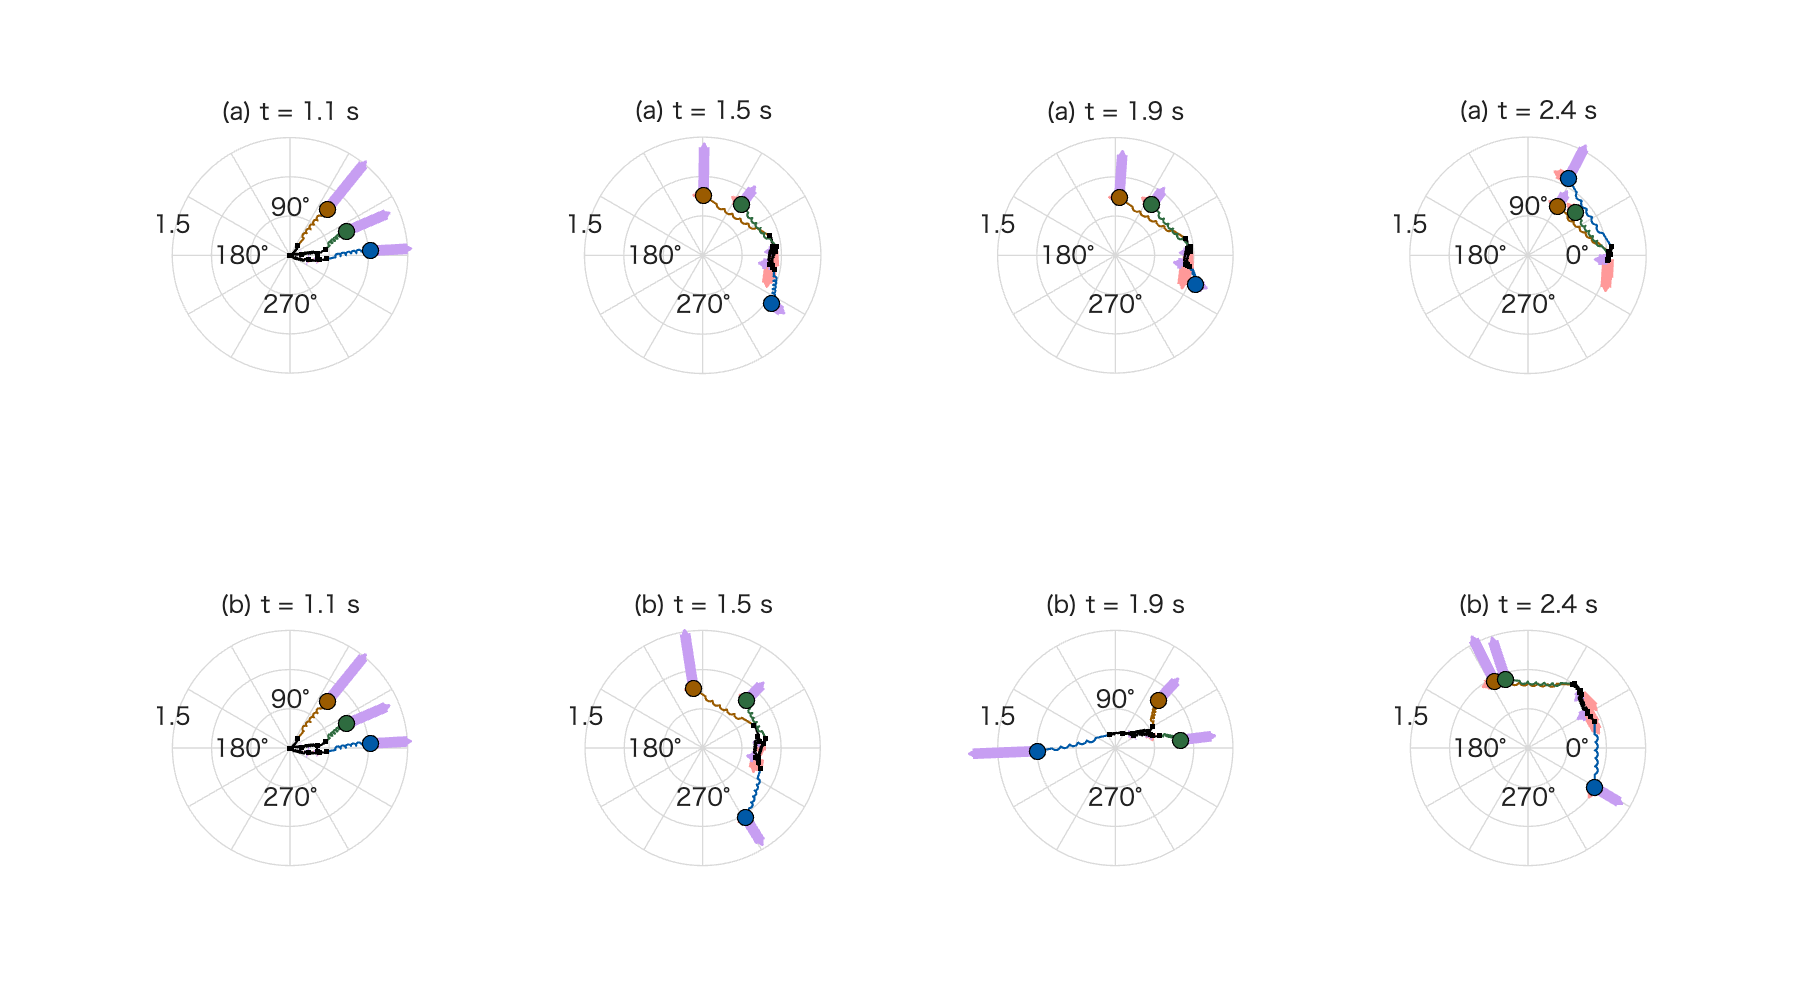

rr_clear = [0.15, 0.20];         % 除去までの時間 [s]
rr_t = [1.1, 1.5, 1.9, 2.4];     % 描く時刻 [s]
sr_row = ["a", "b"];
c_resF = cell(1, 2);
figure(Position=[100 100 900 500]);
layout = tiledlayout(numel(rr_clear), numel(rr_t), TileSpacing="compact", Padding="compact");
for i_case = 1:numel(rr_clear)
    sc = net.add_scenario("fault" + i_case, Time=[0, 3]);
    sc.add_fault("B007", [1, 1 + rr_clear(i_case)]);
    c_resF{i_case} = net.simulate(sc.s_tag, Progress="none");
    for i_t = 1:numel(rr_t)
        ax = nexttile(layout);
        G = c_resF{i_case}.plot_spring_model(Parent=ax);
        G.ShowLabel = false;
        G.ShowValue = false;
        G.ShowLegend = false;
        G.RotationScale = 0;
        G.NodeSize = G.NodeSize * 0.4;
        G.set_style("B001SG1", Color=c_blue);
        G.set_style("B002SG1", Color=c_orange);
        G.set_style("B003SG1", Color=c_green);
        G.set_time(rr_t(i_t));
        title(ax, sprintf("(%s) t = %.1f s", sr_row(i_case), rr_t(i_t)), FontWeight="normal", FontSize=9);
    end
end

verdict = [c_resF{1}.judge_out_of_step().Verdict, c_resF{2}.judge_out_of_step().Verdict]

verdict = 1×2 の string 配列
    "stable"    "out-of-step"


t = 1.1 s（地絡の間）では、地絡が母線 7 を中心に押さえ、まわりの母線を内側へ引き込んでいます。(a) 0.15 秒で除去すると、発電機の点（橙が発電機 2）は前へ走り出しますが、ばねに引き戻されて揺れながら戻ります。(b) 0.20 秒で除去すると、t ≈ 1.9 s で発電機 1（青）とほかの発電機の間のばねが中心をまたぐほど伸び、発電機どうしがずれていきます。これが脱調です。0.05 秒の違いで、ばねが「引き戻せる範囲」を越えるかどうかが分かれます。

**注意**: 図の動きは `G.animate()` で再生でき、`G.export_video("fault.mp4")` で動画（MPEG-4）に保存できます。ライブスクリプトの出力には動きが残らないので、ここでは時刻を選んで並べています。

## 6. 3D で見る電圧崩壊：漏斗を滑り落ちる

定電力負荷は自分の点を持たず、3 節の力 $f_i$ で、つながる母線に働くだけです。円に沿って後ろへ向かうトルク $P$ と、消費する無効電力 $Q$ による、中心へ向かう力 $Q/|V|$ です。後者には危うい性質があります。負荷は電圧がいくらでも同じ $Q$ を求めるので、電圧が低いほど、点を中心へ引き込む力が強くなるのです。電圧が下がると引く力が強まり、電圧がさらに下がります。この繰り返しが電圧崩壊の引き金です。

平らな平面の上では、この様子は見えにくいままです。そこで平面に形を与え、各点を次の高さに持ち上げます。


$$z = \log|V|, \qquad \frac{\mathrm{d}z}{\mathrm{d}|V|} = \frac{1}{|V|}$$


点は漏斗の上を動くことになります。$|V|$ が 1 前後の縁ではほとんど平らで、底に向かうほど急になる曲面です（$\log$ は自然対数で、$|V| = 1$ で $z = 0$）。無効電力 $Q$ は、位置エネルギー $U = Q\,z = Q\log|V|$ を持つ一定の重さとして働かせます。このエネルギーが平面の上に生む力はその傾きで、


$$-\frac{\mathrm{d}U}{\mathrm{d}|V|} = -\frac{Q}{|V|}$$


となり、ちょうど負荷が中心へ引く力と一致します。漏斗が急なところほど、同じ重さでも内向きの力は強くなります（電圧が半分なら 2 倍）。

4 節の古典モデル・定電力負荷の系統で、t = 1 s から母線 5 で消費する無効電力を毎秒 0.05 pu ずつ増やします（`add_input` に時刻と値の表を渡すと、その間を直線で結んだ時系列になります）。

netCl2 = build_classical_ieee9();
netCl2.initialize();
scRamp = netCl2.add_scenario("collapse", Time=[0, 13]);
scRamp.add_input("B005LPQ1", "Qload", [0, 0; 12, -0.6], [1, 13]);
[resRamp, flag] = netCl2.simulate("collapse", Progress="none");

flag

flag = -1

`flag` が −1 で、シミュレーションは終わりの時刻の前に止まりました（上の警告）。止まるまでの時刻は `resRamp.rv_t(end)` です。この先では、無効電力の負荷を支える電圧の解がなくなります。t = 0、6、11、12 s の様子を、漏斗の上に描きます（`Dimension=3`、知識ページの図）。母線 5 を橙で大きく描き、共通の回転は除きます。

resRamp.rv_t(end)

ans = 12.1424

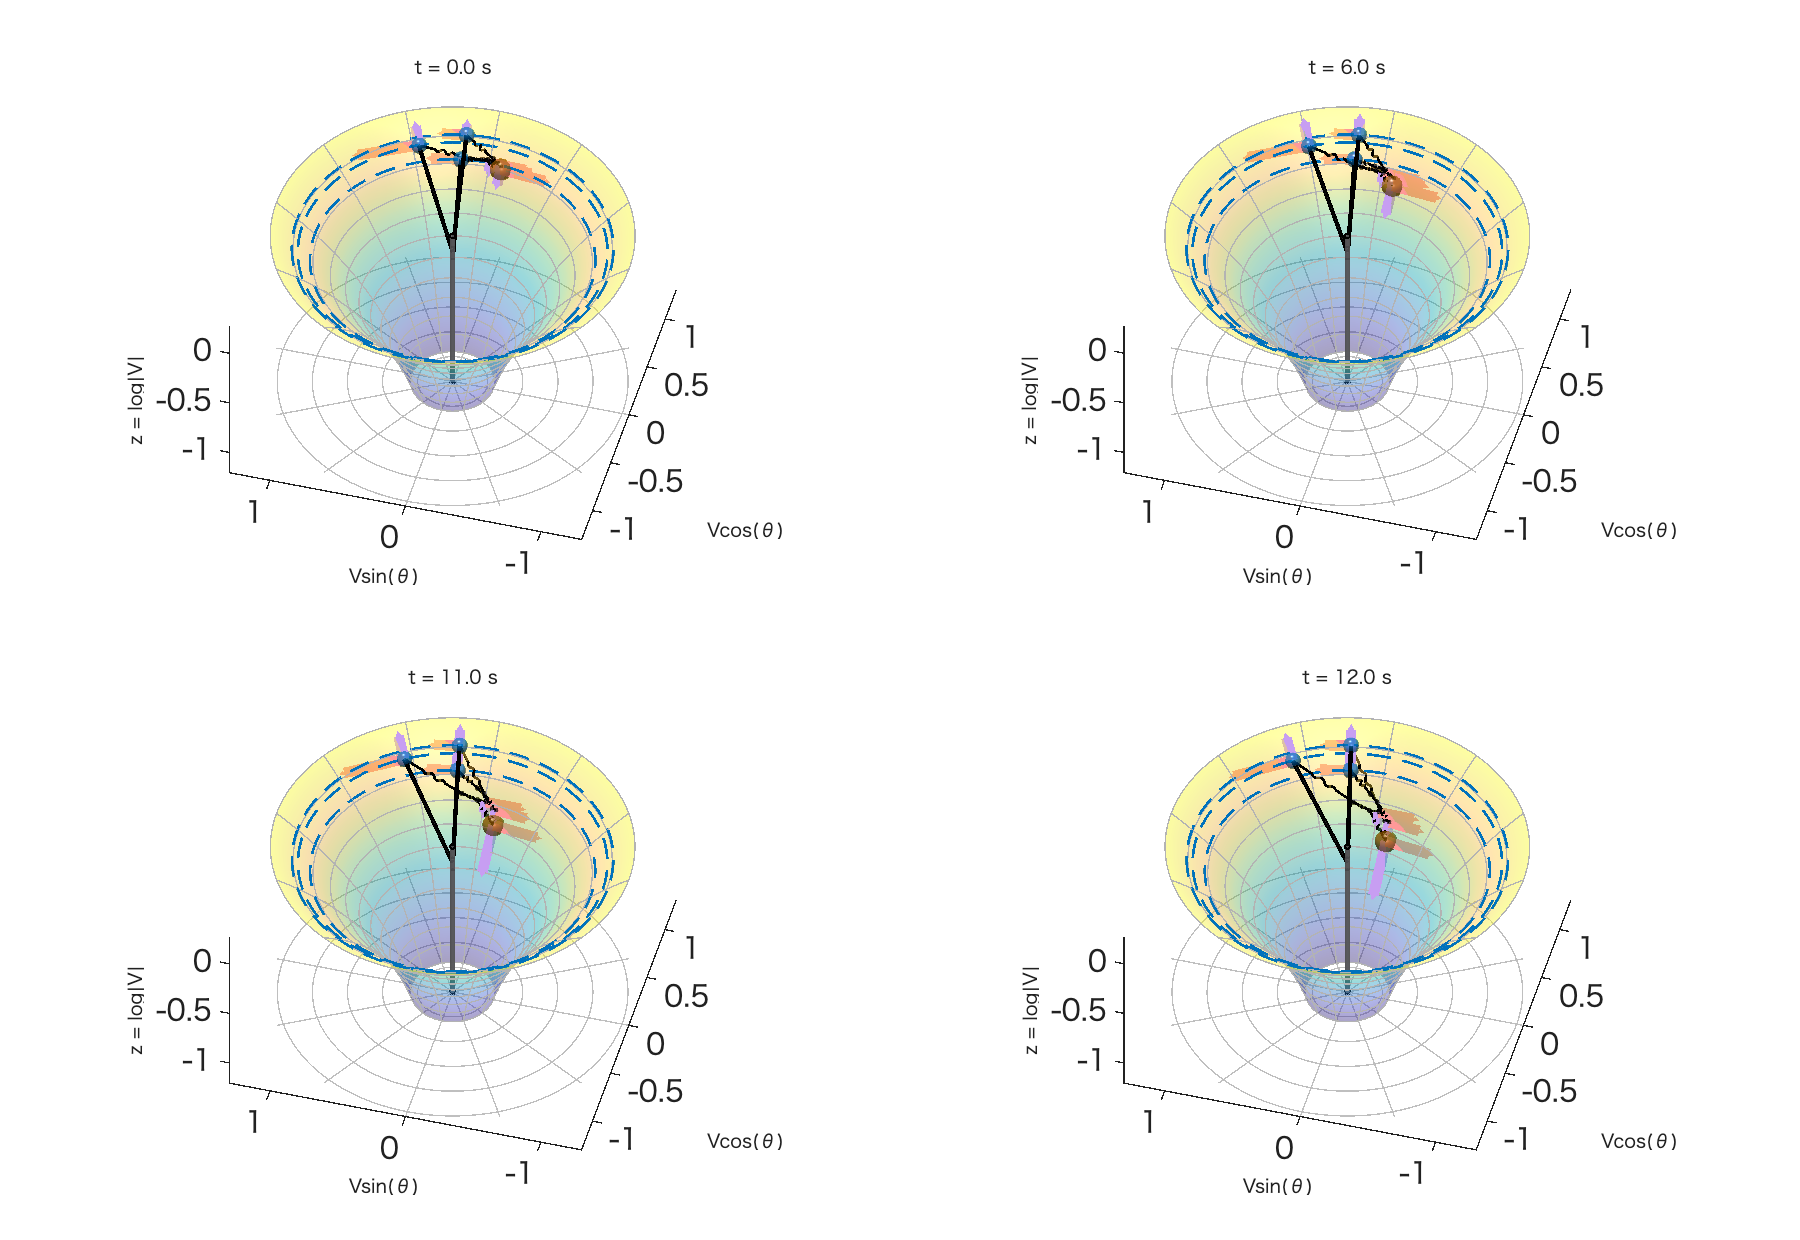

rr_t = [0, 6, 11, 12];
figure(Position=[100 100 900 620]);
layout = tiledlayout(2, 2, TileSpacing="compact", Padding="compact");
for i = 1:numel(rr_t)
    ax = nexttile(layout);
    G = resRamp.plot_spring_model(Dimension=3, Parent=ax);
    G.ShowLabel = false;
    G.ShowValue = false;
    G.ShowLegend = false;
    G.RMin = 0.3;
    G.RMax = 1.3;
    G.View = [-75, 45];       % 母線が漏斗の奥の壁に見える向き
    G.RotationScale = 0;
    G.set_style("B005", Color=c_orange, MarkerSize=20);
    G.set_time(rr_t(i));
    set(findall(ax, "Type", "text"), FontSize=7);
    title(ax, sprintf("t = %.1f s", rr_t(i)), FontWeight="normal");
end

橙の点が母線 5 です。無効電力の負荷が増えると、母線 5 の点が漏斗の斜面を少しずつ下ります。下りるほど斜面は急になり、内向きの力も強まります。電圧の大きさで確かめます。

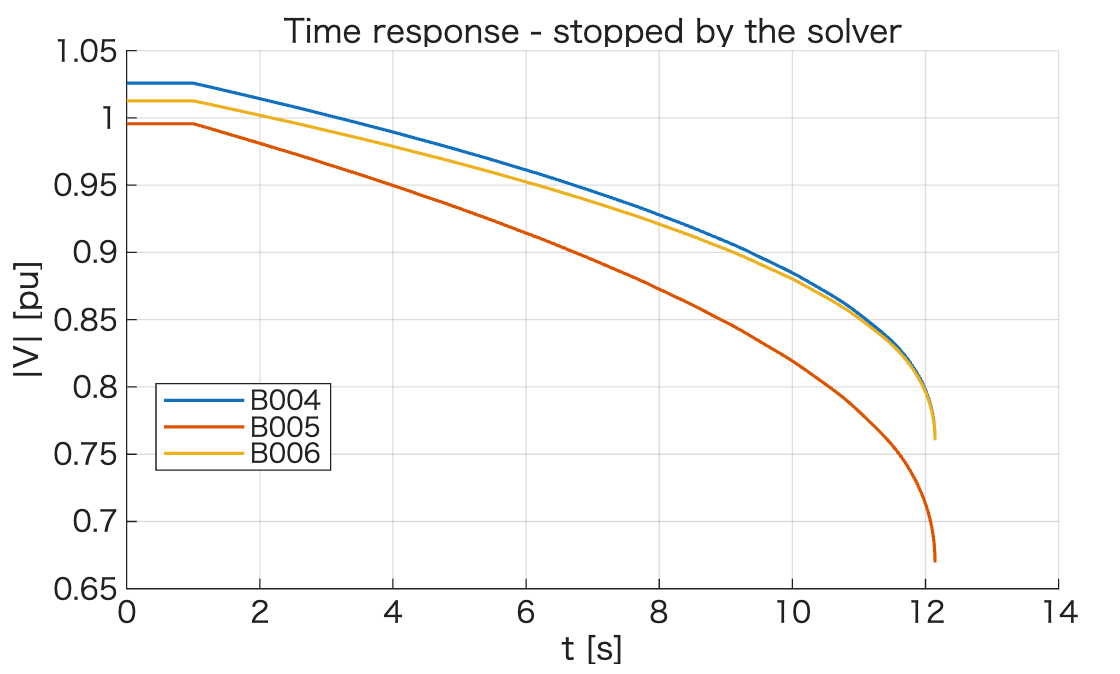

resRamp.plot_trajectory(Quantity="Vabs", Bus=["B004", "B005", "B006"]);

母線 5 の電圧は、はじめはゆっくり、最後は急に下がり、1.0 pu から約 0.67 pu まで下がったところで計算が止まります。無効電力の増え方は一定なのに、電圧の下がり方は加速していきます。ばねが点を支えきれなくなり、点が加速しながら漏斗の底へ落ちていくのです。電圧崩壊は「方程式の解がなくなる」というだけのことではなく、質点が漏斗を滑り落ちる運動として見ることができます。

漏斗は、2 種類の電力のつながりも見せてくれます。平面の向きでは、有効電力が点を中心のまわりに回します（$P$ と $\delta$ の関係）。高さの向きでは、無効電力が点を上下させます（$Q$ と $V$ の関係）。点は曲がった面の上に縛られているので、一方の向きの動きが、もう一方の向きの力を変えます。

**注意**

- 3D の図の `G.RMin` と `G.RMax` は描く曲面の範囲 [pu]、`G.View` はカメラの向き（方位角と仰角）、`G.SurfaceAlpha` は曲面の不透明度です。図の上でマウスで回すこともできます。

- 1 つの図で `G.animate()` を呼ぶと、図が動き出します（`G.animate(Speed=0.5)` で半分の速さ）。知識ページのアニメーションは、この図を `animate` で再生したものと同じです。

- 定インピーダンス負荷では、電圧が下がると無効電力も減るので、このような崩壊は起こりにくくなります。この節で負荷を定電力負荷にしたのはそのためです。

## 7. GUILDA でばね質点モデルを描く

この Part の図は、すべて `plot_spring_model` という名前のメソッドで描きました。どれも、母線を点、発電機の内部電圧をその発電機自身の点、ブランチと発電機のリアクタンスをばねとして描き、有効電力 $P$ と無効電流 $I_q$ の矢印を添えます。

- **平衡点**（`net.plot_spring_model`）: `net.initialize()` の後の平衡点を 1 枚の絵に描きます（3 節）。

- **潮流計算の結果**（`pf.plot_spring_model`）: 母線だけを描きます。潮流計算は発電機の状態を求めないからです（3 節）。

- **シミュレーションの結果**（`res.plot_spring_model`）: 出力したすべての時刻を持ちます。`set_time` で時刻を選び、`animate` で再生し、`export_video` で動画に保存します（4〜6 節）。

- **2D と 3D**（`Dimension=2`、`Dimension=3`）: フェーザの平面、または漏斗 $z = \log|V|$ の上に描きます（6 節）。

出力 `G` は図のオブジェクトです。よく使う設定は次のとおりです。

- `G.ShowValue`（矢印の値）、`G.ShowLabel`（点の名前）、`G.ShowLegend`（凡例）で表示を切り替え、`G.ArrowScaleP` と `G.ArrowScaleQ` で矢印の長さを変えます。

- `G.set_style(タグ, Color=..., MarkerSize=...)` で、点やばねの見た目を 1 つずつ変えます。タグは母線（`B005` など）、発電機（`B002SG1` など）、ブランチのタグです。

- `G.RotationScale = 0` で母線に共通の回転を除いて描きます（既定の 1 は実際の回転）。

- `G.ax` が図の軸で、`axis(G.ax, ...)` のように MATLAB の普通の軸の操作ができます。

GUILDA の発電機のモデル（古典・1 軸・2 軸・Park・ドループ）は、どれも内部電圧を自分の点として持ちます。負荷は自分の点を持たず、その働きは母線の矢印として現れます。

## まとめ

- 定格の周波数で回る座標から見ると、各母線の電圧は平面上の点 $V_i = |V_i|e^{j\theta_i}$ になります。周波数の変化は、すべての点の共通の回転として見えます。

- 送電線は、ばね係数 $B = 1/X$ のばねで、その力は線路電流の $-j$ 倍です。円に沿う向きのトルクが有効電力、中心へ向かう力が無効電流 $Q/|V|$ に対応することを、潮流計算の結果で確かめました。

- 潮流計算の解は、すべてのばねがつり合う位置です。負荷を増やすと、ばねが伸びて角度の差が開きます。

- 負荷が増えると絵全体が後ろへ回り（周波数の低下）、発電機の質量（慣性）がその動き出しをゆるやかにします。慣性を半分にすると、初めの下がる速さは 2 倍になります。ガバナは回転を遅くします。

- ばねが引き戻すトルクは 90° で最大です。事故の除去が遅れて、ばねが支えきれないところまで押し出された点は、円を回って滑ります。これが脱調です。

- 漏斗 $z = \log|V|$ の上では、無効電力は位置エネルギー $Q\log|V|$ を持つ一定の重さになり、電圧崩壊は点が漏斗の底へ滑り落ちる運動として見えます。

## 次の Part

Part 5「近似線形化」では、平衡点のまわりの小さな揺れを線形モデルで表し、固有値から揺れの型を読み取ります。知識ページ: [Part 5: 近似線形化](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part5-linearization.html","-browser"))

[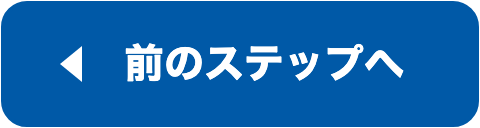](matlab:open('Part3_TimeSimulation.mlx'))　　[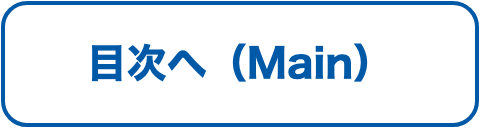](matlab:open('Main.mlx'))　　[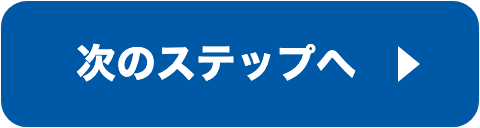](matlab:open('Part5_Linearization.mlx'))

## このライブスクリプトで使う関数

同梱の IEEE 9 母線系統を読み込み、3 台の発電機を古典モデル（$M$ と $D$ は同梱のデータ、$X_d = X_q = X_d'$）に、3 つの負荷を定電力負荷に置き換えた系統を返します。

function net = build_classical_ieee9()
    net = network.IEEE9bus(LocalController=true);
    s_state = warning("off", "GUILDA:Bus:ControllersDropped");   % AVR・PSS が外れる警告を止める
    c_restore = onCleanup(@() warning(s_state));
    tab_dyn = net.get_parameter("dynamics", Key="gen-1axis");     % 発電機 → 古典モデル
    for s_gen = string(tab_dyn.Properties.RowNames)'
        tab_p = renamevars(tab_dyn(s_gen, ["M", "D", "Xd_p"]), "Xd_p", "Xd");   % Xd = Xd'
        tab_p.Xq = tab_p.Xd;                                                    % Xq = Xd'
        net.get_element(s_gen).a_Bus.replace_component(s_gen, "gen-classical", tab_p);
    end
    tab_comp = net.get_element_table(Kind="component");           % 負荷 → 定電力負荷
    tab_comp = tab_comp(tab_comp.Key == "load-impedance", :);
    for k = 1:height(tab_comp)
        net.get_element(tab_comp.Bus(k)).replace_component(tab_comp.Tag(k), "load-power");
    end
end